Defining 2 classes with given data (Base on Sergios Theodoridis, Aggelos Pikrakis, Konstantinos Koutroumbas, Dionisis Cavouras - Introduction to Pattern Recognition_ A Matlab Approach-Academic Press (2010).pdf)

randn('seed',0); 
mu1=[4, 11]'; mu2=[10, 3]';
mu=[mu1 mu2];
S(:,:,1)=3*eye(2); %Sigma_1
S(:,:,2)=3*eye(2); %Sigma_2
P=[0.6 0.4];
N=200; %100 for each
[X,y]=generate_gauss_classes(mu,S,P,N);

Finding decision surface

g1 = @(x) -0.5 * (x - mu1)' * inv(S(:,:,1)) * (x - mu1) + log(P(1));
g2 = @(x) -0.5 * (x - mu2)' * inv(S(:,:,2)) * (x - mu2) + log(P(2));

syms x1 x2
f = g1([x1; x2]) - g2([x1; x2]) == 0;
solve(f)

$$ans = \frac{\left(\mathrm{real}\left(x_{2}\right)-3\right)\,\left(\frac{\mathrm{real}\left(x_{2}\right)}{6}-\frac{1}{2}\right)}{2}-\frac{\left(\mathrm{real}\left(x_{2}\right)-11\right)\,\left(\frac{\mathrm{real}\left(x_{2}\right)}{6}-\frac{11}{6}\right)}{2}+\frac{129752894585949221}{18014398509481984}$$

% Compute simplified symbolic expression
simplifiedExpr2 = simplify(ans)

$$simplifiedExpr2 = \frac{4\,\mathrm{real}\left(x_{2}\right)}{3}-\frac{115144474507647889}{54043195528445952}$$

Plot the final result along with 2 classes

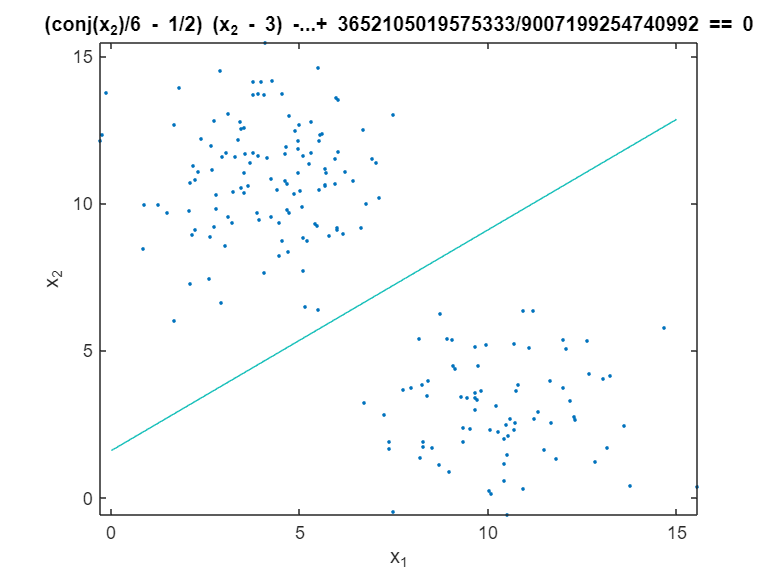

ezplot(f, [0 15 0 15]);
hold on;
plot(X(1,:),X(2,:),'.');